# Clase 06 >> Transformada de Fourier

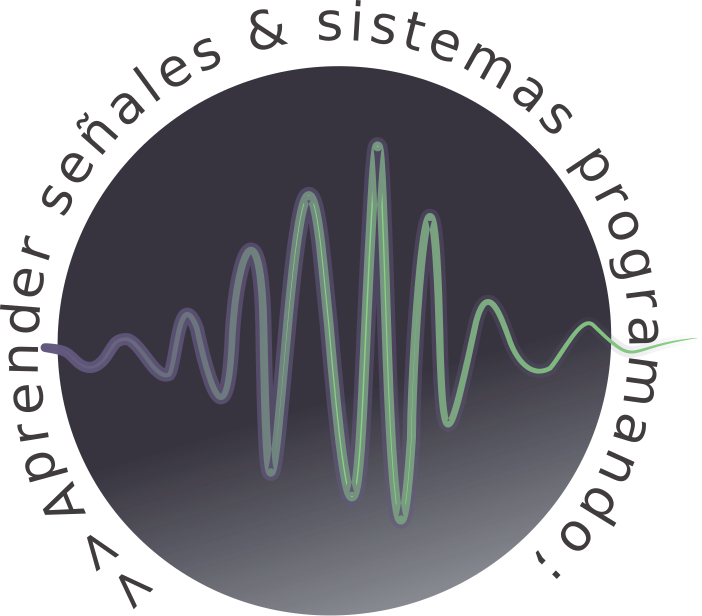

# Temario:

- Introducción.

- Condiciones de Dirichlet.

- Par de transformadas de Fourier.

- Implementación código.

- Señales con simetría par o impar.

# Introducción

Una característica importante de la representación de la serie de Fourier de una señal periódica es la descripción de dicha señal en términos del contenido de frecuencia dado por las componentes sinusoidales. Es entonces surge la pregunta **¿Qué pasa con las señales no periódicas, pueden describirse en términos de contenidos de frecuencia?**

La respuesta es **SI**, y la construcción analítica para hacerlo es la transformada de Fourier.

Como veremos, las componentes de frecuencia de señales no periódicas están definidas para todos los valores reales de la variable de frecuencia $\omega$, y no sólo para los valores discretos de $\omega$ como en el caso de una señal periódica. En otras palabras, el espectro para una señal no periódica, no es el espectro de magnitudes (a menos que la señal sea igual a la suma de sinusoides) [Kamen, 2008]. 

De manera resumida se presenta en la sigueinte tabla:

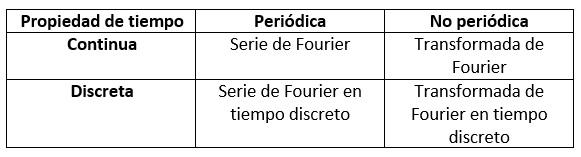

Dada una señal $x(t)$, la transformada de Fourier $X(\omega)$ de $x(t)$ está definida para que sea la función de frecuencia.

# Condiciones de Dirichlet

Dada una señal $x(t)$, la transformada de Fourier $X(j\omega)$ o $X(i\omega)$ de $x(t)$ está definida por:


$$X(j\omega)=\int_{-\infty}^{\infty}{x(t)e^{-j\omega t}dt}, \text{ -\infty<\omega<\infty}$$


Donde $\omega$ es la variable continua de frecuencia. Debido a la presencia de la exponencial compleja $e^{-j\omega t}$, los valores de $X(j\omega)$puden ser complejos. Por lo tanto, en general, la transformada de Fourier$X(j\omega)$ es una función valuada en complejos de la variable de frecuencia $\omega$, y pra especificar $X(j\omega)$, en general es necesario desplegar la función magnitud$\vert X(j\omega)\vert$y la fución ángulo $\angle X(j\omega)$. 

Si la función $x(t)$es tal que:

- Debe ser absolutamente integrable sobre cualquier periodo, osea


$$\int_T |x(t)|dt<\infty$$


- Tiene a lo sumo un número finito de máximos y mínimos y un número finito de discontinuidades en cualquier intervalor finito. entonces la representación en integral de Fourier $X(j\omega)$ converge a $x(t)$en todo punto donde $x(t)$es continua y al promedio de los límites derecho e izquiero de $x(t)$donde $x(t)$es discontinua (esto quiere decir que converge al promedio de la discontinuidad).

La primera condicion implica que el área absoluta debajo de la gráfica de $y=x(t)$es finita. Es es asi si $x(t)$decae suficientemente rápido con el tiempo.

Un ejemplo de una señal que no cumple con las condiciones de Dirichlet es una constante, como se prueba a continuación:

syms t w X
X = int(1*exp(-1i*w*t),t,-inf,inf);
X = simplify(X)

$$X = \begin{array}{l} \left\{ \begin{array}{cl} \left(-\frac{\mathrm{i}}{w}\right)\,\infty & \text{ if }\mathrm{imag}\left(w\right)<0\wedge 0<w\,\mathrm{i}\\ -\frac{\left(\lim_{t\to -\infty }\sigma_{2}\right)\,\mathrm{i}}{w} & \text{ if }\mathrm{imag}\left(w\right)<0\wedge \neg 0<w\,\mathrm{i}\\ \frac{\mathrm{i}}{w}\,\infty & \text{ if }0<\mathrm{imag}\left(w\right)\wedge 0<-w\,\mathrm{i}\\ \frac{\left(\lim_{t\to \infty }\sigma_{2}\right)\,\mathrm{i}}{w} & \text{ if }0<\mathrm{imag}\left(w\right)\wedge \neg 0<-w\,\mathrm{i}\\ 0 & \text{ if }w\neq 0\wedge \sigma_{3}\in \sigma_{1}\wedge \sigma_{4}\in \sigma_{1}\\ \int_{-\infty }^{\infty }\sigma_{2}\mathrm{d}t & \text{ if }\left(0\leq \mathrm{imag}\left(w\right)\vee \neg 0<w\,\mathrm{i}\right)\wedge \left(\mathrm{imag}\left(w\right)\leq 0\vee \neg 0<-w\,\mathrm{i}\right)\wedge \left(0\leq \mathrm{imag}\left(w\right)\vee 0<w\,\mathrm{i}\right)\wedge \left(\mathrm{imag}\left(w\right)\leq 0\vee 0<-w\,\mathrm{i}\right)\wedge \left(w=0\vee \sigma_{3}\notin \sigma_{1}\vee \sigma_{4}\notin \sigma_{1}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\left(-\frac{\pi }{2},\frac{\pi }{2}\right)\\ \sigma_{2}={\mathrm{e}}^{-t\,w\,\mathrm{i}}\\ \sigma_{3}=\text{angle}\left(-w\,\mathrm{i}\right)\\ \sigma_{4}=\text{angle}\left(w\,\mathrm{i}\right) \end{array}$$

Claramente esta expresion no converge, por lo tanto la integral no converge, entonces una señal constantes no tiene transformada de Fourier en el sentido ordinario (en sentido generalizado si).

**En la práctica las señales usualmente son causales y no duran para siempre, es decir existen solo en un intervalo finito de tiempo, por lo tanto en la práctica las señales que usaremos tendran transformada de Fourier.**

# Par de transformadas de Fourier

Definimos a $X(j\omega)$como la **Transformada de Fourier (análisis)**de $x(t)$:


$$X(j\omega)=\int_{-\infty}^{\infty}x(t)e^{-j\omega t}dt$$


La **antitransformada** de $X(j\omega)$ es:


$$x(t)=\frac{1}{2\pi}\int_{-\infty}^{\infty}X(j\omega)e^{j\omega t} d\omega$$


*Las relaciones anteriores juntas constituyen el ****par de transformadas de Fourier**** y proporcionan una trayectoria entre las representaciones del dominio del tiempo y de la frecuencia de una señal. La primera ecuación expresa *$x(t)$* en el dominio de las frecuencias y es análogo a resolverla en las componentes armónicas con frecuencia *$\omega$* que varía continuamente. Esto contrasta con la representación en serie de Fourier de una señal periódica donde las frecuencias toman valores discretos.*

# Implementación en código

Como se viene mencionando la transformada de Fourier puede utilizarse para determinar el contenido espectral de una señal, para lo cual se recurre a la utilizacion del paquete **Symbolic Math Toolbox** (como en el caso del cálculo de series). Puntualmente 

Existen comandos para calcular tanto la transformada como la transformada inversa de Fourier, `fourier(f) `e `ifourier(F)`, donde tanto `f `como `F `son objetos simbólicos que se han definido. Estos comandos en realidad utilizan el comando `int`. Por ejemplo, `fourier `utiliza el comando `int(f*exp(-i*w*x),-inf,inf),-inf,inf), `donde los límites de integración son $-\infty$ e $\infty$, y la transformada de Fourier de `f `está definida con respecto a la variable independiente $x$. Para las funciones de este texto, en general es más sencillo utilizar directamente `int `[Kamen, 2008].

## Por ejemplo:


$$f(t) = \left\lbrace
\begin{array}{ll}
\text{1-\frac{2\vert t \vert}{\tau}\text{  } si -\tau/2 \le t \le \tau/2 \\
\text{0 en otro caso
\end{array}
\right. 
\end{equation}, $$


Donde $\tau = 1$.

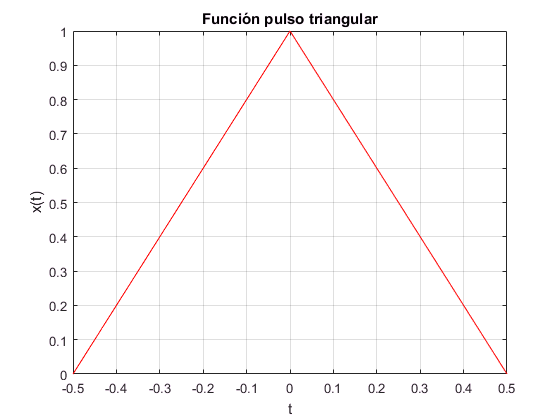

% Dibujar la función de interes
    tau = 1;
    t = [-tau/2:0.001:tau/2]; 
    x = 1-(2*abs(t))/tau;
    plot(t,x,'-r')
        title('Función pulso triangular')
        ylabel('x(t)')
        xlabel('Tiempo (s)')
        grid on       

% Cálculo de la transformada de Fourier
    syms x t w X
    XX = int((1-2*abs(t)/tau)*exp(-1i*w*t),t,-tau/2,tau/2);
    XX = simplify(XX)

$$XX = -\frac{4\,\left(\cos\left(\frac{w}{2}\right)-1\right)}{w^{2}}$$

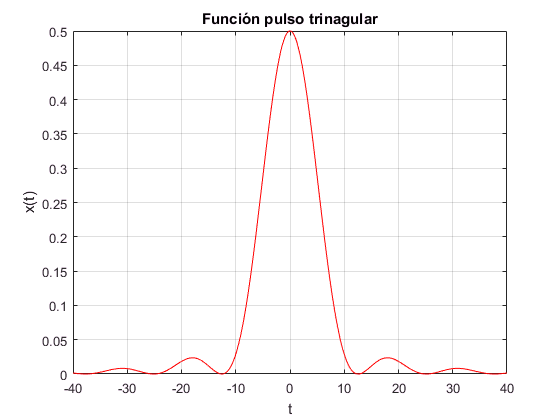

% Dibujar el resultado
    % ezplot(X,[-40 40]) % Proximamente reemplazada
    fplot(XX,[-40 40],'r')
        title('Función pulso trinagular')
        ylabel('x(t)')
        xlabel('Frecuencia (ras/s)')
        grid on

## Ejercicios de la guía "Transformada de Fourier" (script_tf_1)

Resolver el ejercicio n°1, nº2, n°3 y nº4 con un script en MATLAB.

Ejemplo, en el ejercicio nº1, usar la definicion para calcular la Transformada de Fourier de las siguientes funciones:  


$$a) f(t)=e^{-2\alpha (t-1)}u(t-1) \text{    ,con \alpha > 0}$$


# Señales con simetría par o impar

Se dice que una señal $x(t)$ es par si $x(t)=x(-t)$, y se dice que la señal es impar si $x(-t)=-x(t)$. Si la señal $x(t)$ es par, se desprende que la parte imaginaria $I(\omega)$de la transformada de Fourier es cero, y la parte real $R(\omega)$ puede rescribirse como:


$$X(\omega)=2\int_{0}^{\infty}{x(t)cos(\omega t) dt}$$


Si la señal $x(t)$es impar, es decir, $x(t)=-x(-t)$para toda$t>0$, la transformada de Fourier de $x(t)$es una función de $\omega$ totalmente imaginaria, dada por:


$$X(\omega)=-j2\int_{0}^{\infty}{x(t)sen(\omega t) dt}$$


## Por ejemplo:

Dado un número fijo positivo $t$, sea que $p_\tau(t)$ denote el pulso rectangular de duración $t$ segundos definido por:


$$p_\tau(t)= \left\lbrace
\begin{array}{ll}
\text{1\text{  } si -\tau/2 \le t \le \tau/2 \\
\text{0 en otro caso
\end{array}
\right. 
\end{equation}, $$


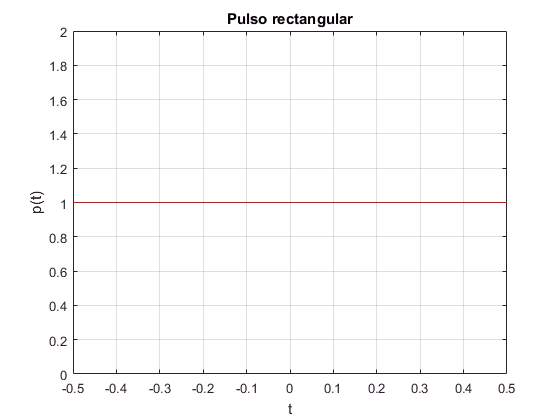

% Dibujar la función de interes
clear all
    tau =1;
    t = [-tau/2:0.001:tau/2]; 
    y = ones(1,length(t));
    plot(t,y,'-r')
        title('Pulso rectangular')
        ylabel('p(t)')
        xlabel('t')
        grid on   

% Cálculo de la transformada de Fourier
    syms x t w X
    tic
    YY = int(1*exp(-1i*w*t),t,-tau/2,tau/2);
    YY = simplify(YY)

$$YY = \frac{2\,\sin\left(\frac{w}{2}\right)}{w}$$

    toc

Elapsed time is 1.078679 seconds.


    tic
    YY = int(1*cos(w*t),t,0,tau/2);
    YY = simplify(2*YY)

$$YY = \frac{2\,\sin\left(\frac{w}{2}\right)}{w}$$

    toc

Elapsed time is 0.516478 seconds.


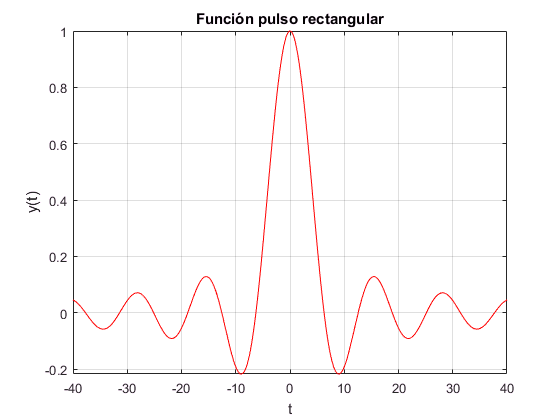

% Dibujar el resultado
    fplot(YY,[-40 40],'r')
        title('Función pulso rectangular')
        ylabel('y(t)')
        xlabel('t')
        grid on    

Si comparamos los resultados de los ultimos dos ejemplos, en el dominio de tiempo, el contenido de alta frecuencia se caracteriza porque la señal cambia rápidamente, como la discontinuidad en el pulso rectangular. Debido a que existen lóbulos laterales tanto en el espectro del pulso triangular como en el del rectangular, es importante observar que los lóbulos laterales del pulso rectangular tienen una amplitud más alta, lo que indica un contenido de frecuencia más alto. Asimismo, el lóbulo principal del pulso triangular es más amplio, lo que indica que en la parte de baja frecuencia del espectro se concentra más energía.  

Vemos que las transiciones más rápidas en el dominio de tiempo indican un contenido alto de frecuencia. Si la duración $\tau$ del pulso rectangular se hace más pequeña, el espectro de amplitud se “expande”. Esto es consistente con la idea de una transición más rápida entre las discontinuidades superior e inferior, lo que indica un contenido más alto de frecuencia. En el límite, conforme la duración del pulso se vuelve infinitesimal, el espectro de amplitud se vuelve constante sobre todas las frecuencias, lo que indica tanto alto contenido de frecuencia en la señal como baja frecuencia.

Agregar

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.